## Ques 4 Part 1

% Load the Boston housing dataset
data = load(['C:\Users\param\OneDrive - Clemson University' ...
    '\Desktop\CU\Fall23\Advance Machine Learning\HW1/housing.data']);

% Extract features and target variable
x = data(:, 1:13);
y = data(:,14);

% Get the number of records (n) and features (d)
[n, d] = size(x);

% Set seed for reproducibility
seed = 2; 
rand('state', seed); 
randn('state', seed);

% Shuffle the dataset
perm = randperm(n); 
x = x(perm, :); 
y = y(perm);

% Split into training and test sets
Ntrain = 300;
Xtrain = x(1:Ntrain, :); 
ytrain = y(1:Ntrain);
Xtest = x(Ntrain+1:end, :); 
ytest = y(Ntrain+1:end);

## Ques4 Part 2

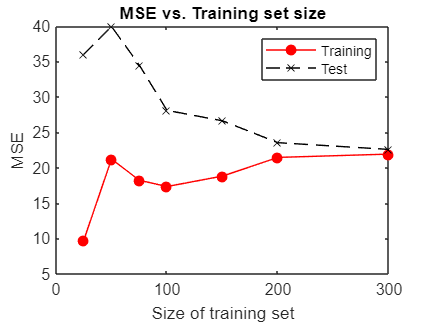

subset_sizes = [25, 50, 75, 100, 150, 200, 300];
num_sizes = numel(subset_sizes);
train_errors = zeros(num_sizes, 1);
test_errors = zeros(num_sizes, 1);

for i=1:num_sizes
    n = subset_sizes(i);
    
    % Extract first n records from training data
    X_sub = Xtrain(1:n, :);
    y_sub = ytrain(1:n);
    
    % Standardize the data
    [X_sub_standardized, mu, sigma] = zscore(X_sub);
    Xtest_standardized = (Xtest - mu) ./ sigma;
    
    % Add offset term (bias/intercept)
    X_sub_standardized = [ones(n, 1), X_sub_standardized];
    Xtest_standardized = [ones(size(Xtest,1), 1), Xtest_standardized];
    
    % Fit linear regression model using least squares
    w = X_sub_standardized \ y_sub;
    
    % Compute MSE for training subset and test set
    train_errors(i) = mean((X_sub_standardized * w - y_sub).^2);
    test_errors(i) = mean((Xtest_standardized * w - ytest).^2);
end

% Plot the results
figure;
plot(subset_sizes, train_errors, '-ro', 'MarkerFaceColor', 'r'); 
hold on;
plot(subset_sizes, test_errors, '--xk'); % Black line with crosses for test error
xlabel('Size of training set');
ylabel('MSE');
legend('Training', 'Test');
title('MSE vs. Training set size');

**Why does the test error decrease as n increases?**

As the training set size increases, the model gets more data to learn from, which generally results in better generalization on unseen data, thus decreasing the test error.

**Why does the train error increase as n increases?**

When the training set is small, the model can fit the training data more closely, sometimes even overfitting it. As the training size increases, the data may become more diverse and harder to fit perfectly, leading to an increase in training error.

**Why do the curves eventually meet?**

As the training set size increases and approaches the full dataset size, the model sees almost all of the available data during training. Consequently, its performance on the training set and the test set becomes more similar, leading to convergence of the two error curves.

## Ques 4 Part 3

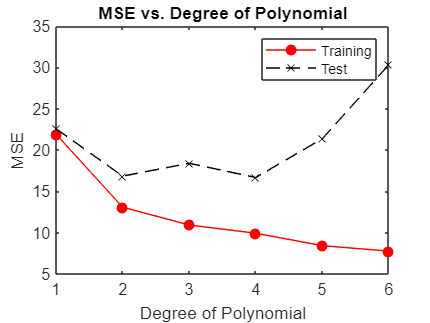

max_degree = 6;
train_errors = zeros(max_degree, 1);
test_errors = zeros(max_degree, 1);

for deg = 1:max_degree
    % Expand the feature set
    Xtrain_exp = degexpand(Xtrain, deg, 1);
    Xtest_exp = degexpand(Xtest, deg, 1);
    
    % Standardize the data
    [Xtrain_exp(:, 2:end), mu2, sigma2] = zscore(Xtrain_exp(:, 2:end));
    Xtest_exp(:, 2:end) = (Xtest_exp(:, 2:end) - mu2) ./ sigma2;
    
    % Train a linear regression model using least squares
    w = pinv(Xtrain_exp' * Xtrain_exp) * Xtrain_exp' * ytrain;

    % Compute the training error
    train_pred = Xtrain_exp * w;
    train_errors(deg) = mean((ytrain - train_pred).^2);
    
    % Compute the test error
    test_pred = Xtest_exp * w;
    test_errors(deg) = mean((ytest - test_pred).^2);
end

% Plot the errors
figure;
plot(1:max_degree, train_errors, '-ro', 'MarkerFaceColor', 'r');
hold on;
plot(1:max_degree, test_errors, '--xk');
xlabel('Degree of Polynomial');
ylabel('MSE');
legend('Training', 'Test');
title('MSE vs. Degree of Polynomial');

**Training Error Decreasing: **

As you increase the polynomial degree, the model has more flexibility and can fit the training data more closely, which reduces the training error.

**Test Error Behavior: **

Initially, the increased flexibility of the model helps to capture the underlying pattern in the data, reducing the test error. However, after a certain point, the model starts to overfit. This means it's fitting the training data too closely, including its noise and outliers. This reduces its ability to generalize to new data, leading to an increase in test error.

## Ques 4 Part 4

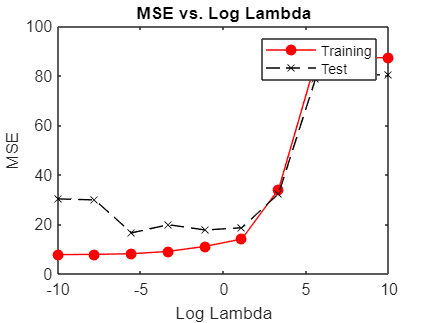

% Expand the feature set
Xtrain_exp = degexpand(Xtrain, 6, 1);
Xtest_exp = degexpand(Xtest, 6, 1);

% Standardize the data
[Xtrain_exp(:, 2:end), mu2, sigma2] = zscore(Xtrain_exp(:, 2:end));
Xtest_exp(:, 2:end) = (Xtest_exp(:, 2:end) - mu2) ./ sigma2;

lambdas = [0 logspace(-10, 10, 10)];

%I = eye(size(Xtrain_exp(:, 2:end), 2));

train_errors = zeros(size(lambdas,1), 1);
test_errors = zeros(size(lambdas,1), 1);
i = 1;

for k = lambdas
    % Compute the X'X term
    XtX = Xtrain_exp' * Xtrain_exp;

    % Construct the regularization term. 
    I = eye(size(XtX, 1));
    I = [zeros(size(XtX, 1), 1), I(:, 2:end)];
    regularization = k * I;

    % Add the regularization to XtX
    ridge_matrix = XtX + regularization;

    % Compute the weight vector w
    w = pinv(ridge_matrix) * Xtrain_exp' * ytrain;

    % Compute the training error
    train_pred = Xtrain_exp * w;
    train_errors(i) = mean((ytrain - train_pred).^2);
    
    % Compute the test error
    test_pred = Xtest_exp * w;
    test_errors(i) = mean((ytest - test_pred).^2);

    i = i + 1;
end

% Plot the errors
figure;

plot(log10(lambdas), train_errors, '-ro', 'MarkerFaceColor', 'r');
hold on;
plot(log10(lambdas), test_errors, '--xk');
%axis([log10(lambdas(2)), log10(max(lambdas)), 0, 90]);
xlabel('Log Lambda');
ylabel('MSE');
legend('Training', 'Test');
title('MSE vs. Log Lambda');

Initially, as *λ* increases from a small value, the added regularization helps combat overfitting, so test error goes down. However, after a certain point, increasing *λ* results in underfitting, causing both training and test error to rise.

## Ques 4 Part 5

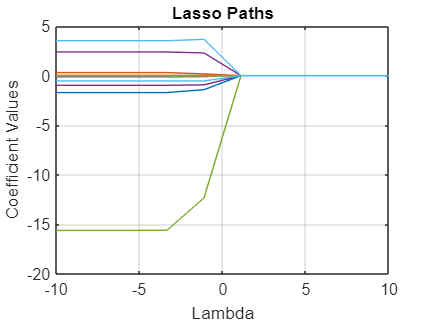

% Define the range of lambda values
lambdas = logspace(-10, 10, 10);

% Use MATLAB's built-in lasso function
[B, FitInfo] = lasso(Xtrain, ytrain, 'Lambda', lambdas);

% Plot
figure;
plot(log10(FitInfo.Lambda), B);
xlabel('Lambda');
ylabel('Coefficient Values');
title('Lasso Paths');
grid on;